# Filtros Municípios administrados pela CAGEPA/ Prefeitura ou Sem Informações

## Equipe: Ca'n'Gica

## Integrantes: Júlia Alves, Lucas Guedes, Lucas Haas, Miguel Marques e Maria Heloisa.

## Instituição: UFPB

municipios_completo = readtable('./InovaHackCAPEGA/municipios_completo.csv');

municipios_completo

municipios_completo = 223×19 table
    Var1    OBJECTID    GEOCODIG_M    UF    Sigla              Nome_Munic                Regi_o       Mesorregi_          Nome_Meso          Microrregi          Nome_Micro           Shape_Leng    Shape_Area                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                          

### Municípios Sem Informações

sem_informacoes = municipios_completo(ismember(municipios_completo.Prestador,'Sem informações'),:);
N_munic_sem_informacoes = size(sem_informacoes.Prestador)

N_munic_sem_informacoes =    149     1


N_munic_sem_informacoes = N_munic_sem_informacoes(1)

N_munic_sem_informacoes = 149

### Municípios Administrados pela CAGEPA

adm_cagepa = municipios_completo(ismember(municipios_completo.Prestador,'Companhia de Águas e Esgotos da Paraíba'),:);
N_adm_cagepa = size(adm_cagepa.Prestador);

N_adm_cagepa = N_adm_cagepa(1)

N_adm_cagepa = 23

### Municípios Administrados por Prefeituras

N_adm_prefeitura = 223 - N_adm_cagepa - N_munic_sem_informacoes; % 223 cidades da PB
N_adm_prefeitura

N_adm_prefeitura = 51

### Gráfico

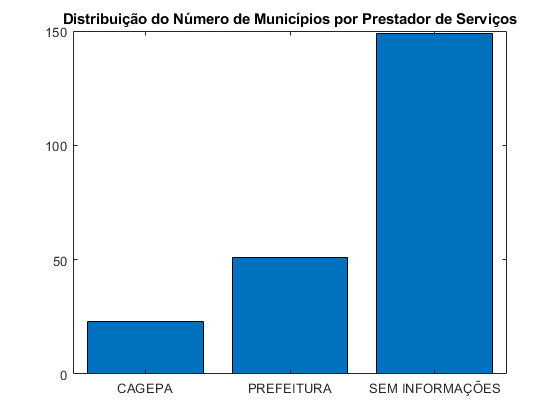

y = [N_munic_sem_informacoes N_adm_cagepa N_adm_prefeitura];
x = categorical({'SEM INFORMAÇÕES', 'CAGEPA', 'PREFEITURA'});
bar(x,y)
title 'Distribuição do Número de Municípios por Prestador de Serviços'

municipios_completo.Nome_Munic(1)

ans = 1×1 cell array
    {'Água Branca'}
